% Import Data

    % Bellvue daily flow
    BLVE_df = readtable("harpeth_river_USGS.xlsx",         ...
                        "Sheet", "BELLVUE_daily_flow",     ...
                        "ReadRowNames", true);
    % Bellvue discrete samples
    BLVE_ds = readtable("harpeth_river_USGS.xlsx",         ...
                        "Sheet", "BELLVUE_discrete_samp",  ...
                        "ReadVariableNames", true);
    % Kingston daily flow
        % As of right now (17.Jan.2020), no data available
    % Kingston discrete samples
    KING_ds = readtable("harpeth_river_USGS.xlsx",         ...
                        "Sheet","KINGSTON_discrete_samp",  ...
                        "ReadVariableNames", true);
    % McDaniel daily flow
    MDNL_df = readtable("harpeth_river_USGS.xlsx",          ...
                         "Sheet", "MCDANIEL_daily_flow",    ...
                         "ReadVariableNames", true);
    % McDaniel discrete sample
    MDNL_ds_opts = detectImportOptions(                      ...
                   "harpeth_river_USGS.xlsx",                ...
                   "Sheet", "MCDANIEL_discrete_samp");
    MDNL_ds_opts = setvartype(MDNL_ds_opts, {'DCOMMENT',     ...
                    'ICOMMENT','SSC'},                       ...
                   {'categorical', 'categorical', 'double'});
    MDNL_ds = readtable("harpeth_river_USGS.xlsx",           ...
                        "Sheet", "MCDANIEL_discrete_samp",   ...
                        "ReadVariableNames", true);

## Group Data by Month

To examine the data by month, I chose the retime() function.  This function will calculate the mean SSC by month. However, it requires a timetable object

% Convert SSC data into timetable
MDNL_SSC_TT = timetable(MDNL_ds.DATETIME, MDNL_ds.SSC, 'VariableNames', {'SSC'});
% Calculate the monthly mean of SSC data
MDNL_SSC_monthly = retime(MDNL_SSC_TT, 'monthly', 'mean');

% Set up NaN data to receive monthly data
MDNL_mth_grp_SSC = NaN([13 12]);

% Use find() function to gather the indices that correspond with each month
    % Jan
    Jan_idx = find(month(MDNL_SSC_monthly.Time) == 1);
        % Take the monthly data and put it into the monthly data matrix set
        % up in the prevous step (MDNL_mth_grp_SSC).  Each column
        % corresponds to a month
        MDNL_mth_grp_SSC(1:length(Jan_idx),01) = MDNL_SSC_monthly.SSC(Jan_idx);
    % Feb
    Feb_idx = find(month(MDNL_SSC_monthly.Time) == 2);
        MDNL_mth_grp_SSC(1:length(Feb_idx),02) = MDNL_SSC_monthly.SSC(Feb_idx);
    % Mar
    Mar_idx = find(month(MDNL_SSC_monthly.Time) == 3);
        MDNL_mth_grp_SSC(1:length(Feb_idx),03) = MDNL_SSC_monthly.SSC(Mar_idx);
    % Apr
    Apr_idx = find(month(MDNL_SSC_monthly.Time) == 4);
        MDNL_mth_grp_SSC(1:length(Apr_idx),04) = MDNL_SSC_monthly.SSC(Apr_idx);
    % May
    May_idx = find(month(MDNL_SSC_monthly.Time) == 5);
        MDNL_mth_grp_SSC(1:length(May_idx),05) = MDNL_SSC_monthly.SSC(May_idx);
    % Jun
    Jun_idx = find(month(MDNL_SSC_monthly.Time) == 6);
        MDNL_mth_grp_SSC(1:length(Jun_idx),06) = MDNL_SSC_monthly.SSC(Jun_idx);
    % Jul
    Jul_idx = find(month(MDNL_SSC_monthly.Time) == 7);
        MDNL_mth_grp_SSC(1:length(Jul_idx),07) = MDNL_SSC_monthly.SSC(Jul_idx);
    % Aug
    Aug_idx = find(month(MDNL_SSC_monthly.Time) == 8);
        MDNL_mth_grp_SSC(1:length(Aug_idx),08) = MDNL_SSC_monthly.SSC(Aug_idx);
    % Sep
    Sep_idx = find(month(MDNL_SSC_monthly.Time) == 9);
        MDNL_mth_grp_SSC(1:length(Sep_idx),09) = MDNL_SSC_monthly.SSC(Sep_idx);
    % Oct
    Oct_idx = find(month(MDNL_SSC_monthly.Time) == 10);
        MDNL_mth_grp_SSC(1:length(Oct_idx),10) = MDNL_SSC_monthly.SSC(Oct_idx);
    % Nov
    Nov_idx = find(month(MDNL_SSC_monthly.Time) == 11);
        MDNL_mth_grp_SSC(1:length(Nov_idx),11) = MDNL_SSC_monthly.SSC(Nov_idx);
    % Dec
    Dec_idx = find(month(MDNL_SSC_monthly.Time) == 12);
        MDNL_mth_grp_SSC(1:length(Dec_idx),12) = MDNL_SSC_monthly.SSC(Dec_idx);
    

## Analyze

% One-Way ANOVA
[AV, tbl, stats] = anova1(MDNL_mth_grp_SSC);


## Visualize

% Boxplot
bx1 = boxplot(MDNL_mth_grp_SSC, "Notch", "off");

bx1 =     0.0022    8.0001   15.0001   22.0001   29.0001   36.0001   43.0001   50.0001   57.0001   64.0001   71.0001   78.0001
    2.0015    9.0001   16.0001   23.0001   30.0001   37.0001   44.0001   51.0001   58.0001   65.0001   72.0001   79.0001
    3.0009   10.0001   17.0001   24.0001   31.0001   38.0001   45.0001   52.0001   59.0001   66.0001   73.0001   80.0001
    4.0004   11.0001   18.0001   25.0001   32.0001   39.0001   46.0001   53.0001   60.0001   67.0001   74.0001   81.0001
    5.0001   12.0001   19.0001   26.0001   33.0001   40.0001   47.0001   54.0001   61.0001   68.0001   75.0001   82.0001
    6.0001   13.0001   20.0001   27.0001   34.0001   41.0001   48.0001   55.0001   62.0001   69.0001   76.0001   83.0001
    7.0001   14.0001   21.0001   28.0001   35.0001   42.0001   49.0001   56.0001   63.0001   70.0001   77.0001   84.0001


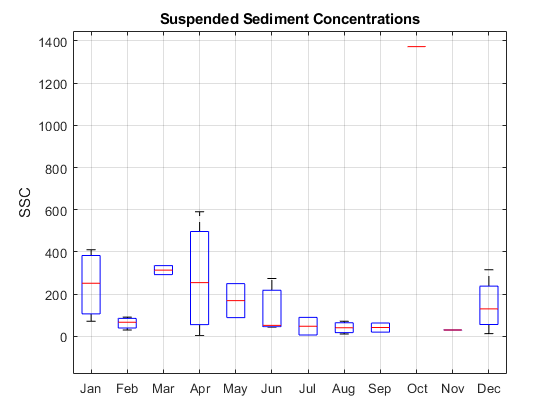

xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', ...
             'Nov', 'Dec'})
title("Suspended Sediment Concentrations")
ylabel("SSC")
grid on